# Ejercicios de optimización de funciones

## Encontrar un máximo o un mínimo local

7.3 Locate the minimum of the function 

*f *(*x*) = 3 + 6*x *+ 5*x^*2 + 3*x^*3 + 4*x^*4 

f = @(x) 3 + 6*x + 5*x.^2 + 3*x.^3 + 4*x.^4

f = function_handle with value:
    @(x)3+6*x+5*x.^2+3*x.^3+4*x.^4


[min, iter,] = nROpt(f, -1, 1)

min = -0.5867

iter = 5

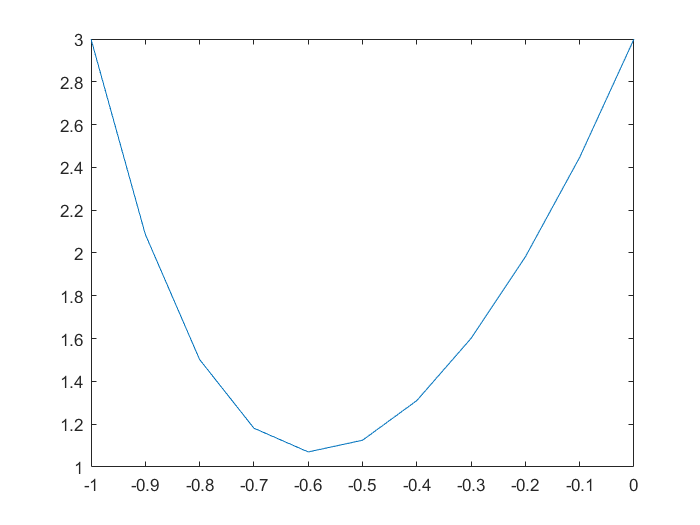

x = -1:0.1:0;
plot(x, f(x))

7.2 Determine the maximum and the corresponding value of x for the function 

*f *(*x*) = −*x^*2 + 8*x *− 12 

f = @(x) -x.^2 + 8*x -12

f = function_handle with value:
    @(x)-x.^2+8*x-12


[max, iter,] = nROpt(@(x) -f(x), -1, 1)

max = 4

iter = 2

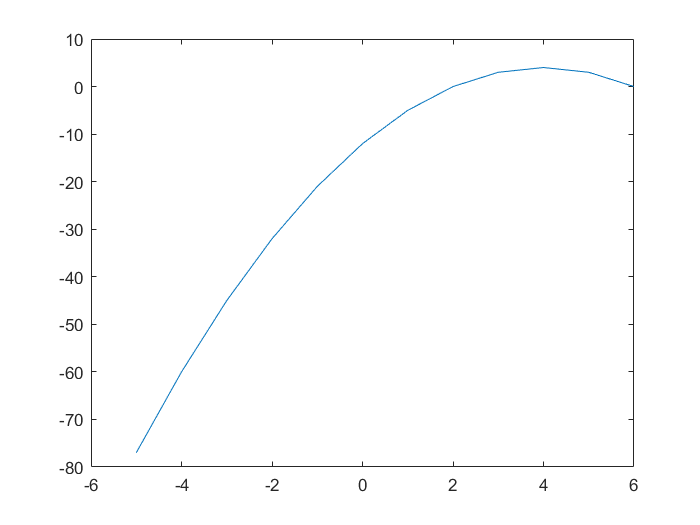

x = -5:1:6;
plot(x, f(x))

7.4 Given 

*f *(*x*) = −1.5*x^*6 − 2*x^*4 + 12*x *

(a) Plot the function. 

f = @(x) -1.5*x.^6 - 2*x.^4 + 12*x

f = function_handle with value:
    @(x)-1.5*x.^6-2*x.^4+12*x


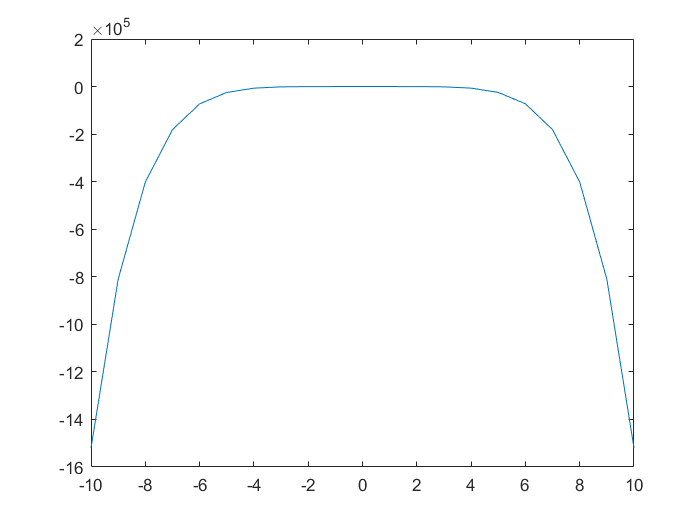

x = -10:1:10;
plot(x, f(x))

(b) Use analytical methods to prove that the function is con­cave for all values of *x*. 

(c) Find the maximum *f*(*x*) and the corre­sponding value of *x*. 

[x, i] = goldenSS(@(x) -f(x), -10, 10)

x = 0.9169

i = 44

## Código de las funciones

Golden section search

function [x, i] = goldenSS(f, a, b)
    REL_TOL = sqrt(eps);
    MAX_ITER = 53;
    x = (a + b) / 2;
    g = (1 + sqrt(5)) / 2 - 1;
    dist = g * (b - a);

    x1 = a + dist;
    f1 = f(x1);
    x2 = b - dist;
    f2 = f(x2);

    i = 0;
    flag = true;
    while flag
        dist = g * dist;
        if f1 < f2
            a = x2;
            x2 = x1;
            f2 = f1;
            x1 = a + dist;
            f1 = f(x1);
        else
            b = x1;
            x1 = x2;
            f1 = f2;
            x2 = b - dist;
            f2 = f(x2);
        end
        x = (a + b) / 2;   
        i = i + 1;
        flag = i < MAX_ITER && abs((b - a) / x) > REL_TOL;     
    end
end

Newton optimization

function [x, i, m] = nROpt(f, a, b)
    REL_TOL = sqrt(eps);
    MAX_ITER = 53;
    x = (a + b) / 2;
    df = diff(sym(f));
    ddf = matlabFunction(diff(df));
    df = matlabFunction(df);
     
    if nargin(ddf) == 0
        ddf = @(x) ddf();
    end
    
    i = 0;
    flag = true;
    while flag
        xp = x;
        x = xp - df(xp) / ddf(xp);
        i = i + 1;
        flag = i < MAX_ITER && abs((x - xp) / x) > REL_TOL;     
    end
    m = ddf(x) > 0;
end